%%% READ ME %%%
% Scriptet virker kun på Matlab 2020 og nyere
% Legg ActualSpeedrun mappen i C:\Users\Username\Documents\MATLAB
% VIEW -> HIDE CODE (for beste visning

addpath('ActualSpeedrun/Funksjoner/') % Legger til folder med funksjoner til matlab path
addpath('ActualSpeedrun/Images') % Legger til folder med bilder i matlab path

% clear all %Obs kan gi treg kode ved å kjøre denne hver gang
clearvars 
% clc
sympref('default'); % Viser polynomialer med lavest orden først

format short

# Funksjoner av flere variable

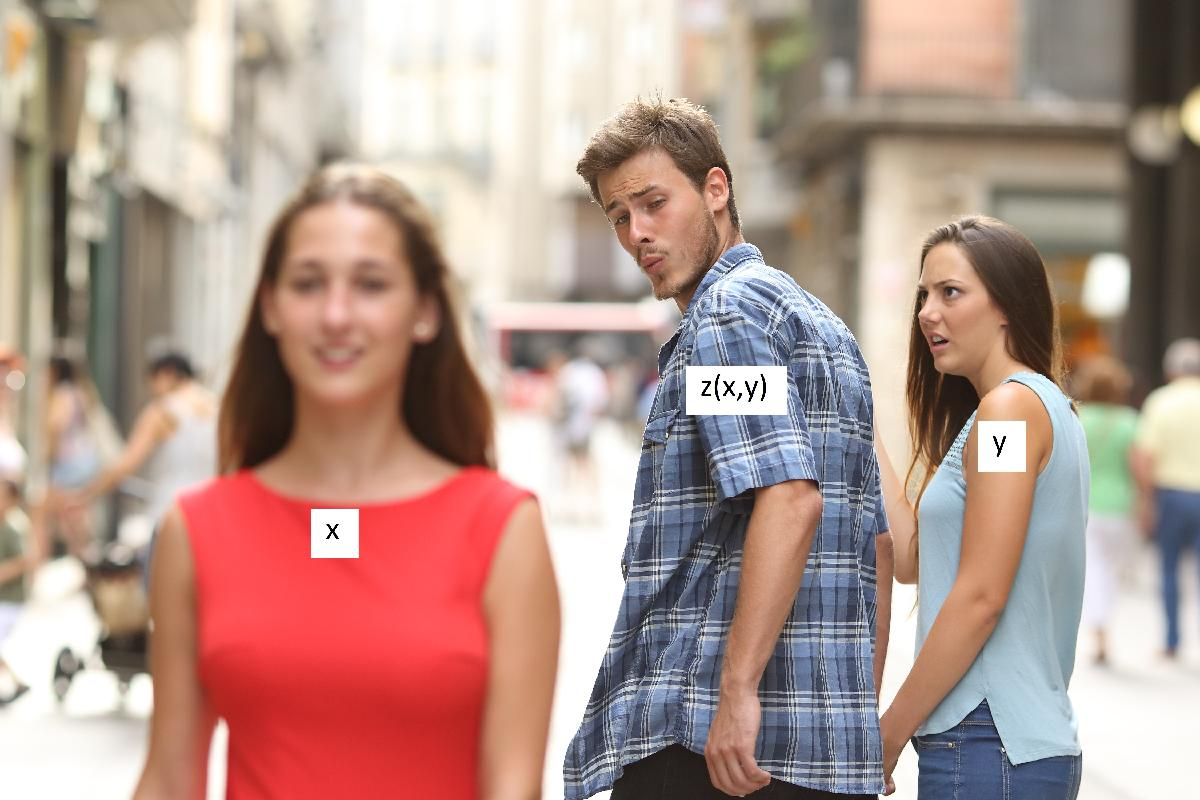

**Input funksjon**

syms x z(x, y)

z(x,y) = y^2*x^2+4; %bruk y og x, eller legg til flere variabler i syms ovenfor
x = 1;
y = 3;
numCheckInp = true; % velger om numeriske verdier for x og y skal evalueres
answerSym = z(x,y);
answerDouble = double(answerSym);


zSimplified = simplify(z);
if numCheckInp == 0 
    if z == zSimplified
    disp(z);    % Viser løsning for z, uten numerisk input
    else
        disp(z == zSimplified);
    end
end

if numCheckInp == 1
    if zSimplified == z && answerSym == answerDouble 
    disp(z == answerSym); % viser løsning for z med symbolsk numerisk input
    elseif zSimplified == z && answerSym ~= answerDouble 
    disp(z == answerSym == answerDouble); % Viser løsning for z med symbolsk numerisk input og som double
    end
end

$$x^{2}\,y^{2}+4=13$$


% Sjekk om z inneholder både x og y
findX = strfind(string(z), 'x');
findY = strfind(string(z), 'y');
if isempty(findX) || isempty(findY)
    disp("ERROR: Bruk funksjon med både x og y")
end
 

disp(func2link(z))

<a href="https://www.wolframalpha.com/input/?i=x%5E2*y%5E2%2B4">Vis funksjon i wolfram</a>


%PLOT er ikke prioritert

**Deriverte**

evalAtX = 0; 
evalAtY = 0;
numCheckDiv = true;
respect1 = 'x';
firstDeriv = diff(z, respect1); % Regner første deriverte
symFirstDeriv = firstDeriv(evalAtX,evalAtY); % Evaluerer symbolsk i forhold til evalAtX og evalAtY 
doubleFirstDeriv = string(double(firstDeriv(evalAtX,evalAtY))); % Evaluerer numerisk som double i forhold til eValAtX og evalAtY


if firstDeriv == doubleFirstDeriv || numCheckDiv == 0   
    disp(firstDeriv);
elseif symFirstDeriv == doubleFirstDeriv && numCheckDiv == 1
    disp(firstDeriv == doubleFirstDeriv); 
elseif numCheckDiv == 1
    disp(firstDeriv == symFirstDeriv == doubleFirstDeriv);
end

$$2\,x\,y^{2}=0$$

respect2 = 'x';
secondDeriv = diff(firstDeriv, respect2);
symSecondDeriv = secondDeriv(evalAtX,evalAtY);
doubleSecondDeriv = string(double(secondDeriv(evalAtX,evalAtY)));


if secondDeriv == doubleSecondDeriv || numCheckDiv == 0
    disp(secondDeriv);
elseif symSecondDeriv == doubleSecondDeriv && numCheckDiv == 1
    disp(secondDeriv == doubleSecondDeriv);
elseif numCheckDiv == 1
    disp(secondDeriv == symSecondDeriv == doubleSecondDeriv);
end

$$2\,y^{2}=0$$

respect3 = 'y';
thirdDeriv = diff(secondDeriv, respect3);
symThirdDeriv = thirdDeriv(evalAtX,evalAtY);
doubleThirdDeriv = string(double(thirdDeriv(evalAtX,evalAtY)));


if thirdDeriv == doubleThirdDeriv || numCheckDiv == 0
    disp(thirdDeriv);
elseif symThirdDeriv == doubleThirdDeriv && numCheckDiv == 1
    disp(thirdDeriv == doubleThirdDeriv);
elseif numCheckDiv == 1
    disp(thirdDeriv == symThirdDeriv == doubleThirdDeriv);
end

$$4\,y=0$$

%% Ta alle varianter og legg i en array eller cell
%% vis cell som tabell men ikke inkluder cellene som blir 0

**Stasjonære punkter**

%% Sjekk at inputfunksjon inneholder både x og y før denne kjører
% if symbolicEmptyY ~= 1 && symbolicEmptyX ~= 1 % symbolicEmpty er hentet fra toppen av koden
    
    syms x y a b 
    firstDerivOfX = diff(z,x);
    firstDerivOfY = diff(z,y);
    [solX, solY] = solve(firstDerivOfX == 0, firstDerivOfY == 0); %løser ligningen når førstederiverte = 0
    
    A = {};

        %%% Finner andrederiverte
        secondDerivofX1 = diff(firstDerivOfX,x); % d^2f/dx^2
        secondDerivofY1 = diff(firstDerivOfY,x); % d^2f/dxdy
        secondDerivofY2 = diff(firstDerivOfY,y); % d^2f/dy^2
        
        secondDerivCheck = secondDerivofX1 * secondDerivofY2 - secondDerivofY1;
        
               
    for i= 1:length(solX)
        %Display stasjonærpunkt
        disp("Stasjonærpunkt " + i + " = " +  "(" + string(solX(i)) +", "+ string(solY(i))+ ")") %display hvert par av x og y
        %Display min, maks eller sadel
        
        
        x = solX(i);
        y = solY(i);
        substitute1 = subs(secondDerivCheck);
        substitute2 = subs(secondDerivofX1);
        
        if substitute1 < 0
                disp("Dette er et sadelpunkt!")
            elseif substitute2 > 0
                disp("Dette er et minimumspunkt!")
            elseif substitute2 < 0
                disp("Dette er et maksimumspunkt!")
            else
                disp("(" + string(solX(i)) +", "+ string(solY(i))+ ") sin andrederiverte gir 0. Utenfor pensum!")
            
        end
        disp(' ')
    end    

Stasjonærpunkt 1 = (0, 0)


(0, 0) sin andrederiverte gir 0. Utenfor pensum!


% end